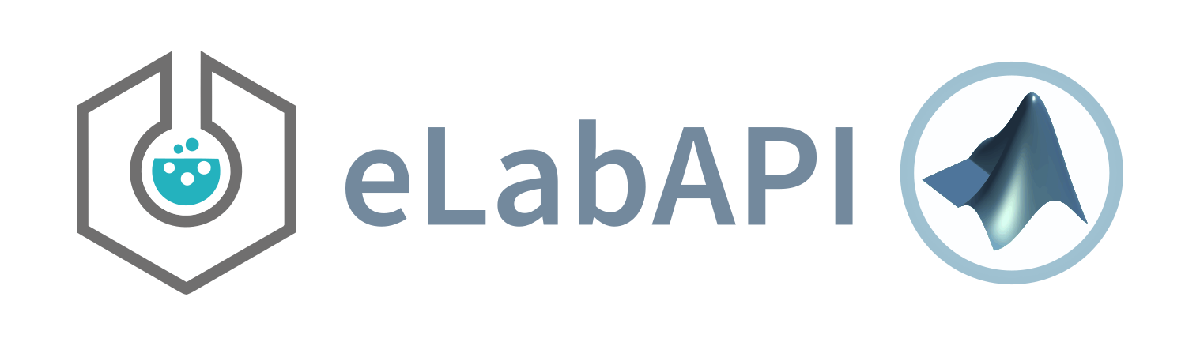

                                                Copyright (c) 2022 Fabien Baillon.

This file is part of **eLabAPI**.

***eLabAPI**** is free software: you can redistribute it and/or modify it under the terms of the GNU General Public License as published by the Free Software Foundation, either version 3 of the License, or any later version.*

*Also see the file "License.mlx".*

# eLabAPI: Example codes of API call functions for eLabFTW

## Getting started

The eLabAPI package is a Matlab version of the eLabFTW API.

This package permits to facilitate working in a matlab environment.

From Matlab, you can access to the eLabAPI documentation by the command:

doc("doc_eLabAPI/")

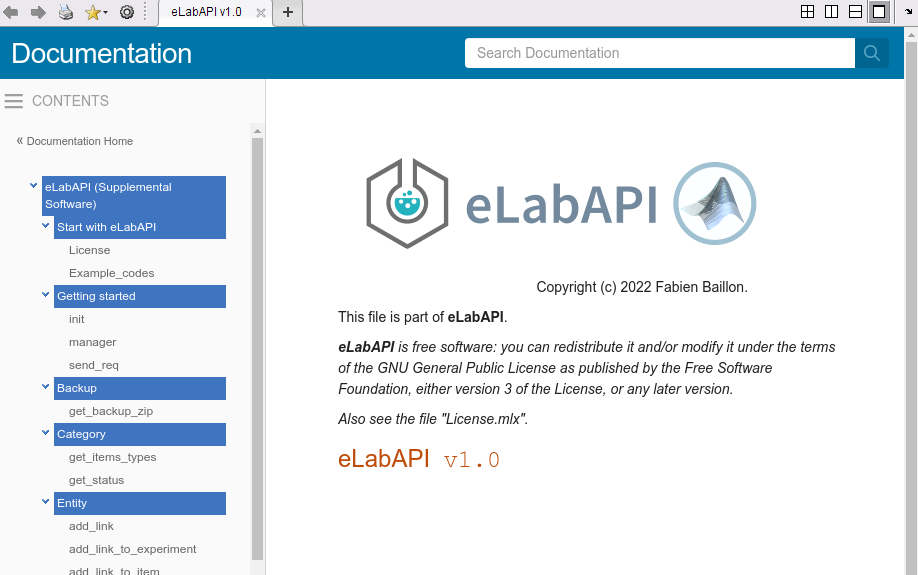

Go to your user control panel and create an API key for your account. This key allows access to your data, keep it secret and secure!

#### manager

initialize the manager with an endpoint and your token

token = "55cde...403157";
endpoint = "https://elab.example.org/api/v1";
%
elabapi.manager(endpoint,token);

     description: "A matlab module to interact with elabftw API"
         version: "0.1.1"
          author: "Fabien BAILLON"
    author_email: "fabien.baillon@imt-mines-albi.fr"
         license: "GPL v3"
       copyright: "Copyright (©) 2022 Fabien BAILLON"



or via a structure

options.token = "55cde...403157";
options.endpoint = "https://elab.example.org/api/v1";
options.pretty_json = true;
%
CONF = elabapi.manager(options);

## Backup

### Get backup zip

####     get_backup_zip

get all modified experiments from last week

day_now =datetime('now','Format','uuuuMMdd');
lastweek = day_now - calweeks(1);
period = string(lastweek)+"-"+string(day_now);
%
elabapi.get_backup_zip(period);

## Category

#### Get the list of id of available items_types

####     get_items_types

[struct_items_types, json_items_types] = elabapi.get_items_types();

### Get the list of status for current team

####     get_status

[struct_status, json_status] = elabapi.get_status();

## Entity

### Add a link

####     add_link

Add link to a specific item

- link database item 106 to experiment 42

RES = elabapi.add_link_to_experiment(42,106); 

or via a structure

params.id = 42;
params.link = 106;
RES = elabapi.add_link_to_experiment(params);

- link database item 106 to database item 42

RES = elabapi.add_link_to_item(42,106);

or via a structure

params.id = 42;
params.link = 106;
RES = elabapi.add_link_to_item(params);

- link database item 106 t to item 42, by specifying its endpoint

RES = elabapi.add_link('items',42,106);

or via a structure

params.id = 42;
params.link = 106;
params.endpoint = 'items';
RES = elabapi.add_link(params);

### Add a tag

####     add_tag

add tag to a specific item

- add tag "some-tag" to experiment 42

RES = elabapi.add_tag_to_experiment(42, "some-tag");

or via a structure

params.id = 42;
params.tag =  "some-tag";
RES = elabapi.add_tag_to_experiment(params);

- add tag "some-tag" to database item 42

RES = elabapi.add_tag_to_item(42, "some-tag");

or via a structure

params.id = 42;
params.tag =  "some-tag";
RES = elabapi.add_tag_to_item(params);

- add tag "some-tag" to item 42, by specifying its endpoint

RES = elabapi.add_tag('items',42, "some-tag");

or via a structure

params.id = 42;
params.tag =  "some-tag";
params.endpoint = 'items';
RES = elabapi.add_tag(params);

### Create a database item

####     create_item

Create a database item,  by specifying its category ID

[RES, json_RES] = elabapi.create_item(16);

or via a structure

params.id = 16;
[RES, json_RES] = elabapi.create_item(params);
fprintf(1,"Created database item with id %d.\n",RES.id);

### Create experiment

####     create_experiment

Create an experiment 

[RES, json_RES] = elabapi.create_experiment();
fprintf(1,"Created experiment with id %d.\n",RES.id);

### Create template

####     create_template

Create template

[RES, json_RES] = elabapi.create_template();
fprintf(1,"Created template with id %d.\n",RES.id);

### Get an upload

####     get_upload

get an upload 

% get upload with id 350
elabapi.get_upload(350);

### Get bookable items

####     get_bookable

Get only the bookable items

[RES, json_RES]= elabapi.get_bookable();

### Read experiments

####     get_all_experiments

Read all experiments

[RES, json_RES] = elabapi.get_all_experiments()

or with options structure


options.limit = 5;              % number max of results
options.offset = 1;             % offset in the database
options.search = 'extrusion';   % search in the title
[RES, json_RES] = elabapi.get_all_experiments(options);

####     get_experiment

Read a specific experiment

[RES, json_RES] = elabapi.get_experiment(100);

### Read items from database

####     get_all_items

Read all items from database

[RES, json_RES] = elabapi.get_all_items()

or with options structure

options.limit = 5;              % number max of results
options.offset = 1;             % offset in the database
options.search = 'Sans';        % search in the title
[RES, json_RES] = elabapi.get_all_items(options);

####     get_item

Read a specific item from database

[RES, json_RES] =  elabapi.get_item(11);

### Read tags

####     get_tags

Read all tags

[RES, json_RES] =  elabapi.get_tags();

### Read templates

####     get_all_templates

Read all templates

[RES, json_RES] = elabapi.get_all_templates();

## Update category

####     update_category

Update category of an experiment or a database item

% update category of database item 42
elabapi.update_category('items',42,19)

or via a structure

params.endpoint = 'experiments';
params.id = 420;
params.category = 6;
% update status of experiment 420
elabapi.update_category(params)

### Update entity

####     post_item

Update elements of a specific item

params.title = 'Title of this item';
params.body = ' <h2>Content</h2>';
params.bodyappend = 'Content body ...<br/> ... with appended content!';
params.date = '20220729';
params.category = 20;
params.link = 19;
params.metadata ='{\"foo\":5,\"bar\":true}';
params.tag = 'some tag';
% update database item 42
RES = elabapi.post_item(42,params);

####     post_experiment

Update elements of a specific experiment

new_exp = elabapi.create_experiment();
%
params.title = 'Title of this experiment';
params.body = ' <h2>Content</h2>';
params.bodyappend = 'Content body ...<br/> ... with appended content!';
params.date = '20220729';
params.category = 6;
params.link = 16;
params.metadata ='{\"foo\":5,\"bar\":true}';
params.tag = 'some tag';
%  update experiment new_exp.id
RES = elabapi.post_experiment(new_exp.id,params);

### Upload a file

####     upload

Upload a file to an experiment

% upload your-file.jpg to experiment 42
filename = 'your-file.jpg';
RES = elabapi.upload('experiments',42,filename);

or via a structure

params.endpoint = 'experiments';
params.id = 42;
params.file = filename;
% upload your-file.jpg to experiment 42
RES = elabapi.upload(params);

Upload a file to a database item

params.endpoint = 'items';
params.id = 16;
params.file = filename;
% upload your-file.jpg to database item 16
RES = elabapi.upload(params);

## Events

### Create event

####     create_event

Create an event in the scheduler for an item

params.start = "2022-07-29T12:00:00+01:00";
params.end = "2022-07-29T14:00:00+01:00";
params.title = "Booked from API";
% book database item 20 on the 29th of July 2022 from noon to 2pm
RES = elabapi.create_event(20, params);

### Destroy event

####     destroy_event

Delete an event

% destroy event with id 13
RES = elabapi.destroy_event(13);

### Get events

####     get_events

Get all the events from the team or just one event if the id is set

RES = elabapi.get_event(2);

%#ok<*NASGU>
%#ok<*ASGLU> 